clc;clear;close all;
vid = videoinput('winvideo','1','MJPG_1024x576');
preview(vid);

disp('按任一鍵開始拍照取像')

按任一鍵開始拍照取像


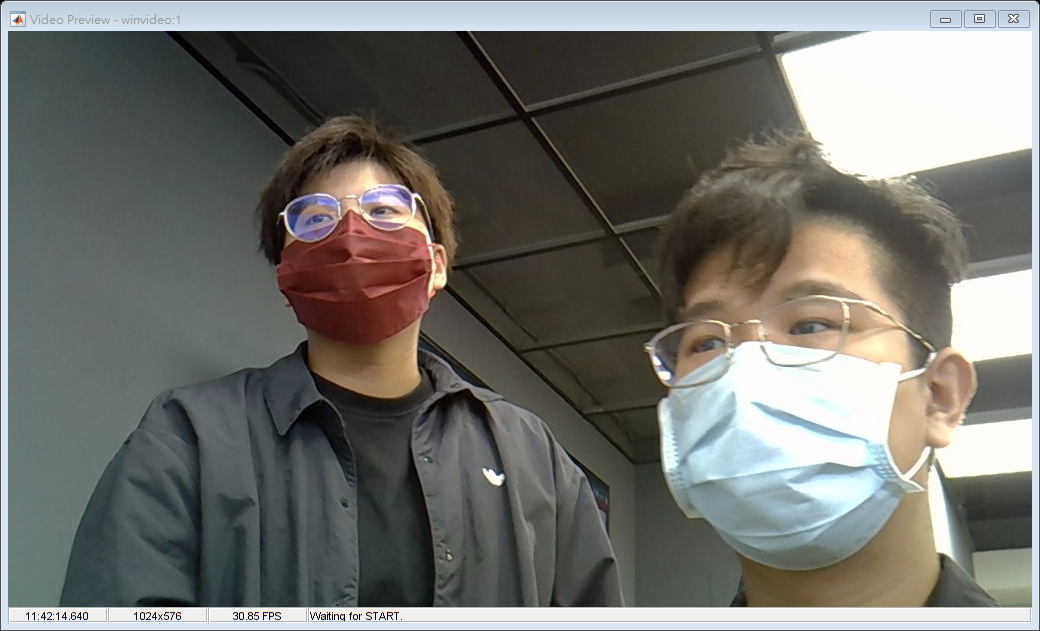

pause

photo = getsnapshot(vid);


gray=rgb2gray(photo)

gray = 576×1024 uint8 matrix
   65   64   64   64   65   65   66   66   66   66   65   64   63   62   61   61   63   63   62   62   62   62   62   62   63   63   63   62   62   61   61   61   61   61   61   61   61   61   60   60   60   60   60   59   58   57   56   56   57   57
   65   65   65   64   65   65   66   66   66   66   65   64   63   62   61   61   63   63   62   62   62   62   62   62   63   63   62   62   62   62   61   61   61   61   61   61   61   61   60   60   60   60   60   59   58   57   56   56   56   57
   66   66   65   65   64   65   65   65   66   65   65   64   63   62   62   61   63   63   62   62   62   62   62   62   63   62   62   62   62   62   62   61   61   61   61   61   61   61   60   60   60   60   60   60   59   58   57   56   56   57
   66   66   65   65   64   64   64   65   65   65   64   64   63   62   62   62   64   63   63   62   62   62   62   63   62   62   62   62   62   62   62   62   61   61   62   62   61   61   60   60   60   60   60   

subplot(2,2,1);imshow(gray)
image=gray

image = 576×1024 uint8 matrix
   65   64   64   64   65   65   66   66   66   66   65   64   63   62   61   61   63   63   62   62   62   62   62   62   63   63   63   62   62   61   61   61   61   61   61   61   61   61   60   60   60   60   60   59   58   57   56   56   57   57
   65   65   65   64   65   65   66   66   66   66   65   64   63   62   61   61   63   63   62   62   62   62   62   62   63   63   62   62   62   62   61   61   61   61   61   61   61   61   60   60   60   60   60   59   58   57   56   56   56   57
   66   66   65   65   64   65   65   65   66   65   65   64   63   62   62   61   63   63   62   62   62   62   62   62   63   62   62   62   62   62   62   61   61   61   61   61   61   61   60   60   60   60   60   60   59   58   57   56   56   57
   66   66   65   65   64   64   64   65   65   65   64   64   63   62   62   62   64   63   63   62   62   62   62   63   62   62   62   62   62   62   62   62   61   61   62   62   61   61   60   60   60   60   60  


[height,width] = size(image)

height = 576

width = 1024

b=[];
b(256)=0;
for k=1:256
    for i=1:height
        for j=1:width
            if image(i,j) == k-1
                b(k)=b(k)+1;
            end;
        end;
    end;
end;
subplot(2,2,3);plot(b);



J=imadjust(gray,[0.2  0.5],[0  1])

J = 576×1024 uint8 matrix
   47   43   43   43   47   47   50   50   50   50   47   43   40   37   33   33   40   40   37   37   37   37   37   37   40   40   40   37   37   33   33   33   33   33   33   33   33   33   30   30   30   30   30   27   23   20   17   17   20   20
   47   47   47   43   47   47   50   50   50   50   47   43   40   37   33   33   40   40   37   37   37   37   37   37   40   40   37   37   37   37   33   33   33   33   33   33   33   33   30   30   30   30   30   27   23   20   17   17   17   20
   50   50   47   47   43   47   47   47   50   47   47   43   40   37   37   33   40   40   37   37   37   37   37   37   40   37   37   37   37   37   37   33   33   33   33   33   33   33   30   30   30   30   30   30   27   23   20   17   17   20
   50   50   47   47   43   43   43   47   47   47   43   43   40   37   37   37   43   40   40   37   37   37   37   40   37   37   37   37   37   37   37   37   33   33   37   37   33   33   30   30   30   30   30   30 

subplot(2,2,2);imshow(J)
image=J

image = 576×1024 uint8 matrix
   47   43   43   43   47   47   50   50   50   50   47   43   40   37   33   33   40   40   37   37   37   37   37   37   40   40   40   37   37   33   33   33   33   33   33   33   33   33   30   30   30   30   30   27   23   20   17   17   20   20
   47   47   47   43   47   47   50   50   50   50   47   43   40   37   33   33   40   40   37   37   37   37   37   37   40   40   37   37   37   37   33   33   33   33   33   33   33   33   30   30   30   30   30   27   23   20   17   17   17   20
   50   50   47   47   43   47   47   47   50   47   47   43   40   37   37   33   40   40   37   37   37   37   37   37   40   37   37   37   37   37   37   33   33   33   33   33   33   33   30   30   30   30   30   30   27   23   20   17   17   20
   50   50   47   47   43   43   43   47   47   47   43   43   40   37   37   37   43   40   40   37   37   37   37   40   37   37   37   37   37   37   37   37   33   33   37   37   33   33   30   30   30   30   30  


[height,width] = size(image)

height = 576

width = 1024

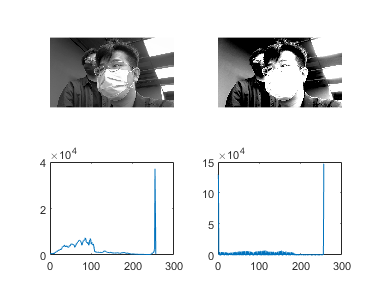

b=[];
b(256)=0;
for k=1:256
    for i=1:height
        for j=1:width
            if image(i,j) == k-1
                b(k)=b(k)+1;
            end;
        end;
    end;
end;
subplot(2,2,4);plot(b);